## **4.1) Loading the Signals**

clear
load("v2.mat");
data1=val(20,:);
load("v4.mat");
data2=val(40,:);
load("v6.mat");
data3=val(60,:);

## 4.2) Plotting Signals in Time Domain

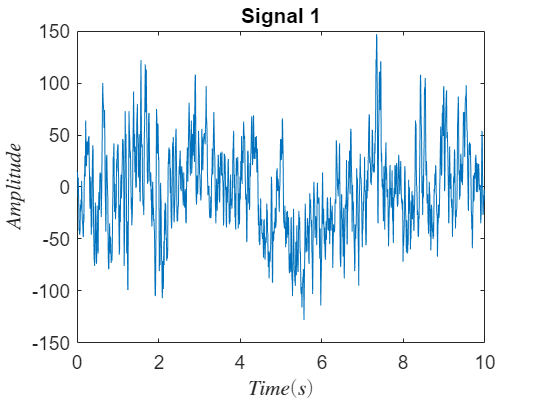

N=length(data1);
fs=N/10;
t=0:1/fs:10-1/fs;
plot(t,data1);
xlabel ('$Time(s)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Signal 1')

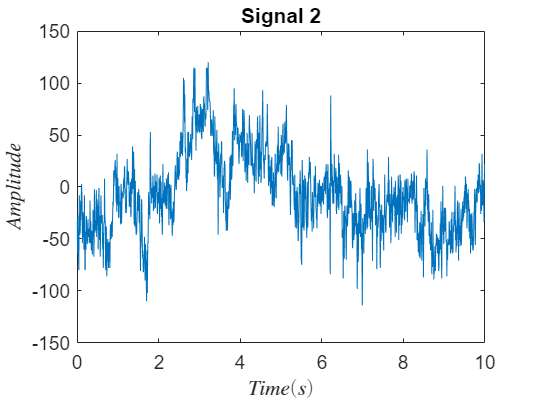

plot(t,data2);
xlabel ('$Time(s)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Signal 2')

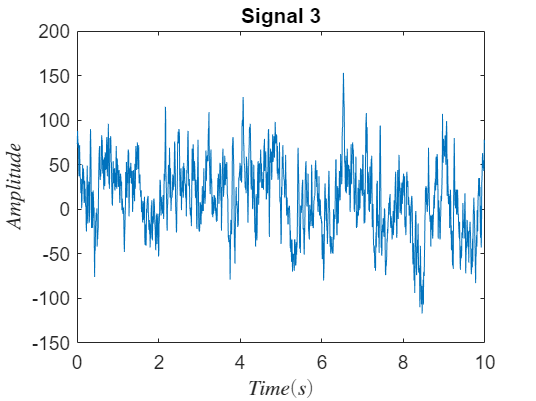

plot(t,data3);
xlabel ('$Time(s)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Signal 3')

## Plotting Signals in Frequency Domain

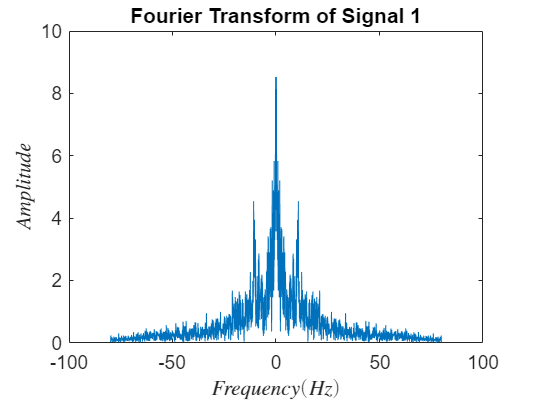

f=-fs/2:fs/N:fs/2-fs/N;
FT_data1=fftshift(fft(data1));
FT_data2=fftshift(fft(data2));
FT_data3=fftshift(fft(data3));
plot(f,abs(FT_data1/N));
xlabel ('$Frequency(Hz)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Fourier Transform of Signal 1')

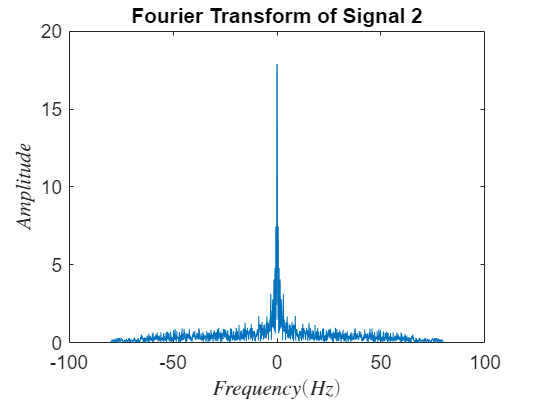

plot(f,abs(FT_data2/N));
xlabel ('$Frequency(Hz)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Fourier Transform of Signal 2')

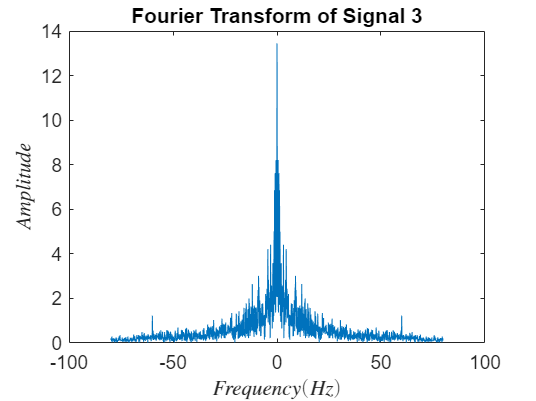

plot(f,abs(FT_data3/N));
xlabel ('$Frequency(Hz)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Fourier Transform of Signal 3')

## 4.4) Extracting Waves

## 
$$\textrm{Gamma}\Rightarrow 35+\textrm{Hz}$$


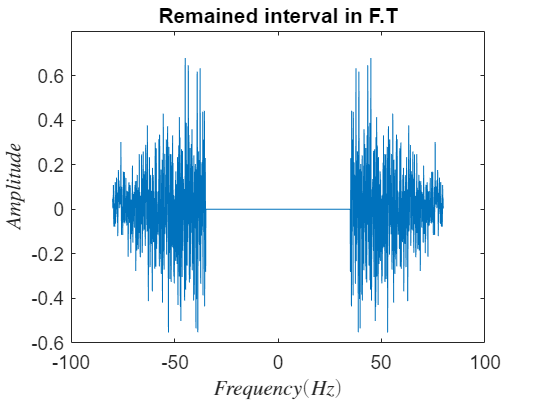

data_Gamma=FT_data1;
data_Gamma(find(f>-35 & f<35))=0;
plot(f,real(data_Gamma/N));
xlabel ('$Frequency(Hz)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Remained interval in F.T')

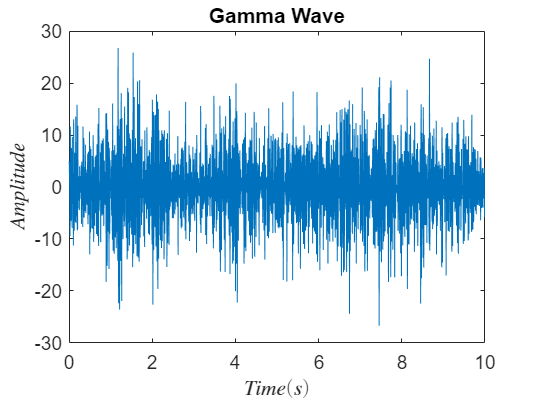

Gamma=ifft(ifftshift(data_Gamma));
plot(t,Gamma);
xlabel ('$Time(s)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Gamma Wave')

## 
$$\textrm{Beta}\Rightarrow 13-35\;\textrm{Hz}$$


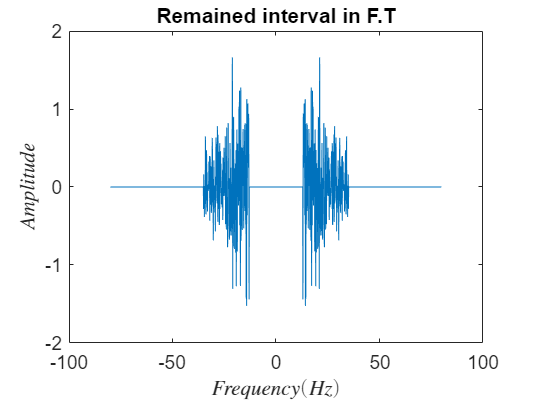

Beta=filter(FT_data1,f,13,35);

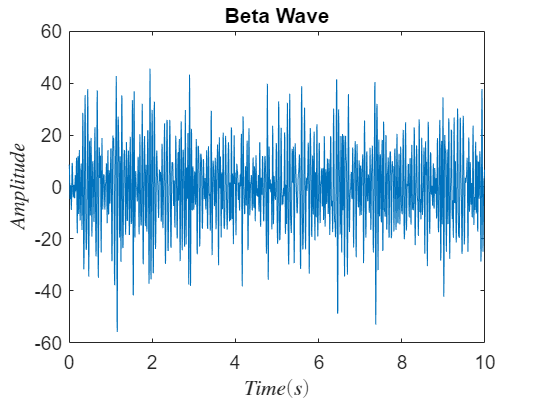

plot(t,Beta);
xlabel ('$Time(s)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Beta Wave')

## 
$$\textrm{Alpha}\Rightarrow 8-13\;\textrm{Hz}$$


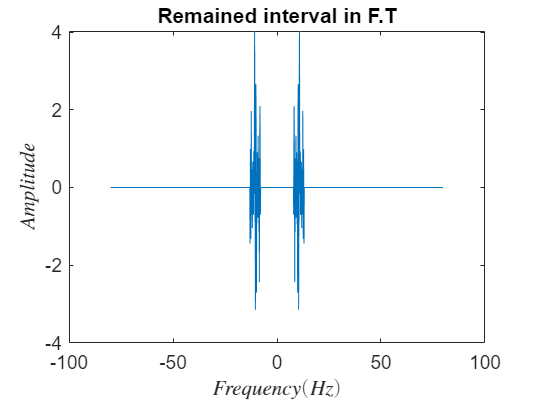

Alpha=filter(FT_data1,f,8,13);

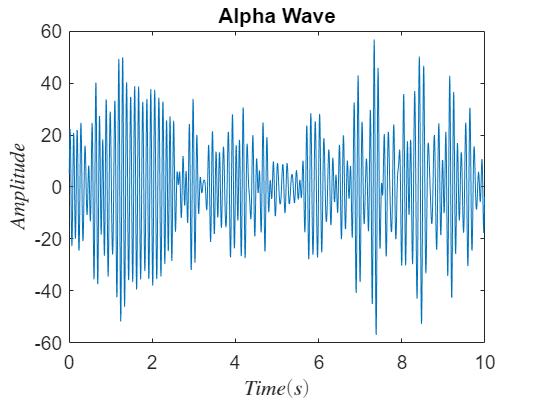

plot(t,Alpha);
xlabel ('$Time(s)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Alpha Wave')

## 
$$\textrm{Theta}\Rightarrow 4-8\;\textrm{Hz}$$


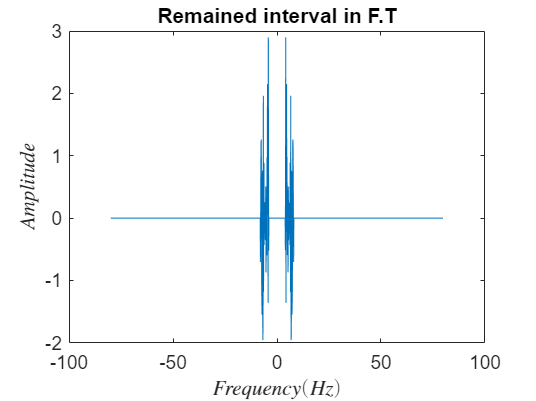

Theta=filter(FT_data1,f,4,8);

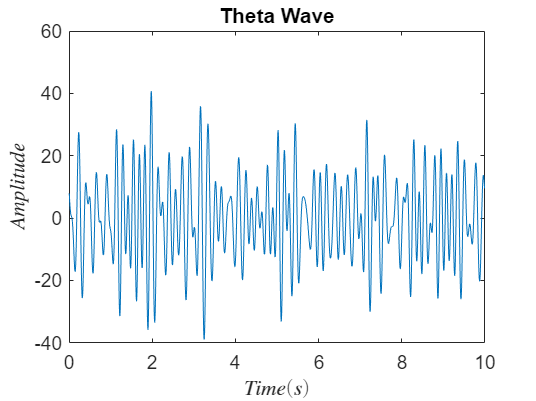

plot(t,Theta);
xlabel ('$Time(s)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Theta Wave')

## 
$$\textrm{Delta}\Rightarrow 0\ldotp 5-4\;\textrm{Hz}$$


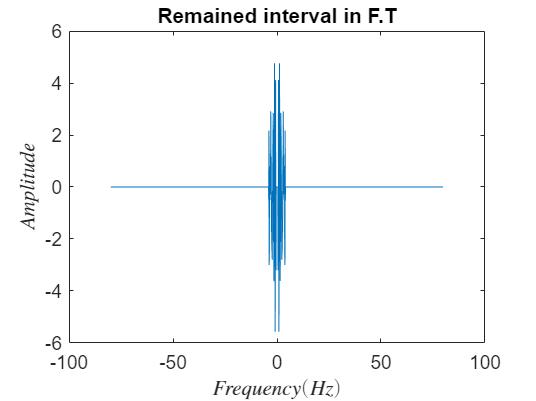

Delta=filter(FT_data1,f,0.5,4);

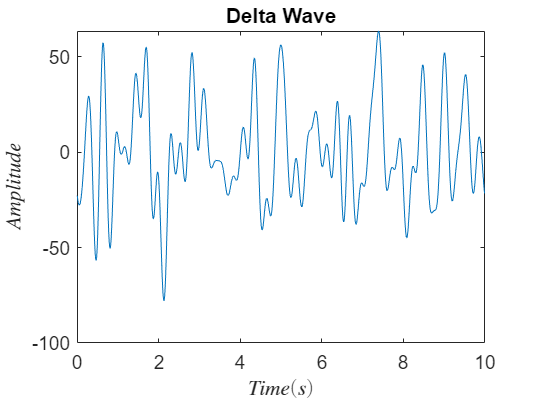

plot(t,Delta);
xlabel ('$Time(s)$','Interpreter','latex')
ylabel ('$Amplitude$','Interpreter','latex')
title ('Delta Wave')

## Filter()

function [wave] = filter(signal,f,start,stop)
    signal(find(f<-stop | f>stop))=0;
    signal(find(f>-start & f<start))=0;
    plot(f,real(signal)/length(signal));
    xlabel('$Frequency(Hz)$','Interpreter','latex')
    ylabel('$Amplitude$','Interpreter','latex')
    title('Remained interval in F.T')
    wave=ifft(ifftshift(signal));
end